# **Reto: Diagnóstico de malaria**

## *F1013B.1*

**Equipo**

**Antonio Jaime López [A01424138]**

**Leonardo Pérez González [A01424133]**

**Manuel Camacho Padilla [A01423135]**

**Denisse Regina García Rivera [A01424207]**

### **Etapa 2**

**Objetivo:**

Desarrollar una **simulación computacional en Matlab** para **calcular y graficar campos eléctricos no uniformes** (los campos eléctricos no uniformes son usados para el diagnóstico de  enfermedades como la malaria y el cáncer, a partir de células  infectadas/enfermas)

ENTREGABLE   

1.-La simulación computacional (en Matlab) debe tener  los siguientes  requisitos :

-  graficar  DOS  LINEAS  CARGADAS  ,UNA ENFRENTE DE   OTRA   tendrán  la  misma  longitud  y misma  carga  pero de signos contrarios  (una  positiva  y otra negativa ) 

- El usuario podrá: 

- ESPECIFICAR el  valor  de la carga de  la  distribución de  carga  lineal 

- La ubicación del inicio de la linea  en los ejes coordenados (  ya se  horizontal  o vertical )

- .GRAFICAR  LAS LINEAS DE CAMPO  ELECTRICO 

- valor del campo   eléctrico   entre las  lineas 

2.-  El reporte   debe  de contener  las ecuaciones   y como se  usaron   en  el    diseño de la simulación  , así como explicar  las   instrucciones  usadas 

#### DESARROLLO DE CÓDIGO DE LAS LINEAS VERTICALES:

Limpiamos nuestra consola, el workspacs, y eliminamos todas las figuras que ya teniamos creadas para evitar problemas en el codigo.

clear all; close all; clc;

Vamos a definir las constantes que usaremos, y las entradas que el usauario va a introducir, y que posteriormente usaremos.

k = 8.98e9;

%División de cargas en la barra
inter = 80; 

%Punto inicial de la barra
pI = input('Ingrese el punto de inicio de la barra: ');

%Longitud de la barra
long=1; 

%--------------------------------------------%
%   Vectores de las barras con linspace()
% linspace permite una distribución uniforme
%--------------------------------------------%
barra_1 = linspace(0,long,inter); 
barra_2 = linspace(0,long,inter);
%--------------------------------------------%

%Valor de la carga
carga=input('Ingrese el valor que tendrá la carga: ')

carga = 3


%Espacio entre las barras
s=0.5; 

%La longitud y la separación se mantienen constantes, aunque podrían ser
%variables indicadas por el usuario


Ahora vamos a crear vectores para distribuir las cargas a lo largo de las barras

barra1 = zeros(1,inter); %Se inicializan estos vectores con el mismo número de intervalos
barra2 = zeros(1,inter);
q1 = zeros(1,inter);
q2 = zeros(1,inter);

Ahora haremos un ciclo para ir desplazando la distrubucion de cargas a lo largo de la barra

for i = 1:inter 
    barra1(i) = pI; 
    barra2(i) = pI + s; % Segunda barra, a partir de la suma del punto de inicio y separación
    q1(i) = -carga/length(q1);
    q2(i) = carga/length(q2);
end

Ahora haremos un vector de coordenadas, para poder graficar todos los datos obtenidos, y su campo eléctrico

x = [barra1, barra2]; 
y = [barra_1, barra_2]; 
cargas = [q1, q2]; % [negativa, positiva]

Ahora vamos a hacer otro vector, para la cantidad de 'Flechitas' que tendremos, mientras mas grande sea la variable 'cantidad' mas exacto se ve

c=30

c = 30

x_i = linspace(pI - s, pI + s * 2, c); %Vector con 30 cargas distribuidas
y_i = linspace(-long, long * 2, c);

Creación del campo vectorial con meshgrid()

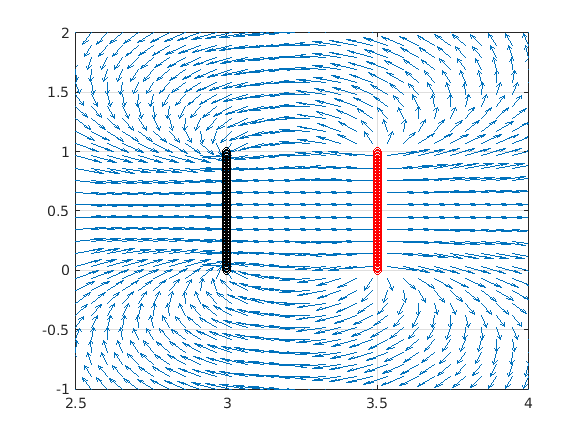

[X_I, Y_I] = meshgrid(x_i,y_i); 
zi = complex(X_I,Y_I);
z = complex(x,y); 
[ZI, Z]= ndgrid(zi(:),z(:)); %ndgrid coloca todo en una columna
dZ = ZI-Z;
Zn = abs(dZ);

%Se escalan las cargas
E = (dZ./Zn.^3) * (cargas(:) * k);
E = reshape(E, size(X_I));
En = abs(E);

Ex = real(E);
Ey = imag(E);

%Graficación de campo vectorial
quiver(X_I,Y_I,Ex./En,Ey./En);

%El eje para mostrar bien las barras
axis([pI - s pI + s * 2 -long long * 2]); 
grid on;
hold on;

plot(pI,barra_1,'ok'); %Primera barra
plot(pI + s,barra_2,'or');  %Segunda barra